clc; clear; close all;

% Given parameters
a = 200; % mm
d_vals = 30:5:500; % mm
d_min = 30; % mm
d_max = 500; % mm

% Calculation of x
x_max = d_max + a;
x = 500;

% Compute y2 directly without iteration
beta = acos((x/2) / (a/2 + d_max/2));
y2 = ((x/2) * tan(beta)) + d_max/2;

% Function to calculate alpha numerically
function alpha = calculate_alpha(a, d_min, x, y2)
    % Define objective function (difference between two l calculations)
    obj_fun = @(alpha) ...
        ((x/2)/sin(alpha) - ((a + d_min) * 0.95 / 2) / sin(alpha)) - ...
        ((1/cos(alpha)) * (y2 - d_min/2 - sin(acos((x - 2*((x/2)/sin(alpha) - ((a + d_min)*0.95/2)/sin(alpha))*sin(alpha)) / (a + d_min))) * (a/2 + d_min/2)));
    
    % Use fzero to find root (alpha where both equations match)
    alpha = fzero(obj_fun, 15 * pi / 180); % Initial guess: 15 degrees
end

% Compute optimized alpha
alpha = calculate_alpha(a, d_min, x, y2);

disp(['Computed alpha: ', num2str(alpha*180/pi)]);

Computed alpha: 17.5874


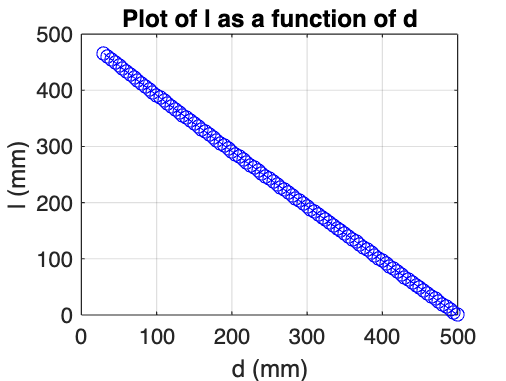


% Precompute sin and cos of alpha for efficiency
sin_alpha = sin(alpha);
cos_alpha = cos(alpha);

% Initialize previous l value
l_prev = (x/2)/sin(alpha) - ((a + d_min)*0.95/2)/sin(alpha);

% Initialize l_vals with first and last values
l_vals = zeros(size(d_vals));

% Compute l values using fzero instead of symbolic solver
for i = 1:(length(d_vals)-1)  
    d = d_vals(i);
    
    % Define function to solve for l numerically
    eq_l = @(l) l - ((1/cos_alpha) * (y2 - d/2 - sin(acos((x - 2*l*sin_alpha) / (a + d))) * (a/2 + d/2)));

    % Solve for l using fzero, with previous l as initial guess
    sol_l = fzero(eq_l, l_prev);

    % Store solution and update l_prev
    l_vals(i) = sol_l;
    l_prev = sol_l;
end

% Plot l as a function of d
figure;
plot(d_vals, l_vals, 'b-o');
xlabel('d (mm)');
ylabel('l (mm)');
title('Plot of l as a function of d');
grid on;


% Display results for d = 500
disp('Results for d = 500 mm:');

Results for d = 500 mm:


disp(['y2: ', num2str(y2)]);

y2: 494.949


disp(['alpha: ', num2str(alpha)]);

alpha: 0.30696


disp(['x: ', num2str(x)]);

x: 500
